# Práctica 9.

#### Ejercicio 1. Aplicación en electrostática.

a) Abrimos desde *pdetool *el archivo llamando `p9ej1.m`; de ahí extraemos la solución aproximada.

pdetool;

Que nos permite obtener a su vez la representación con líneas ispotenciales y las líneas de campo eléctrico.

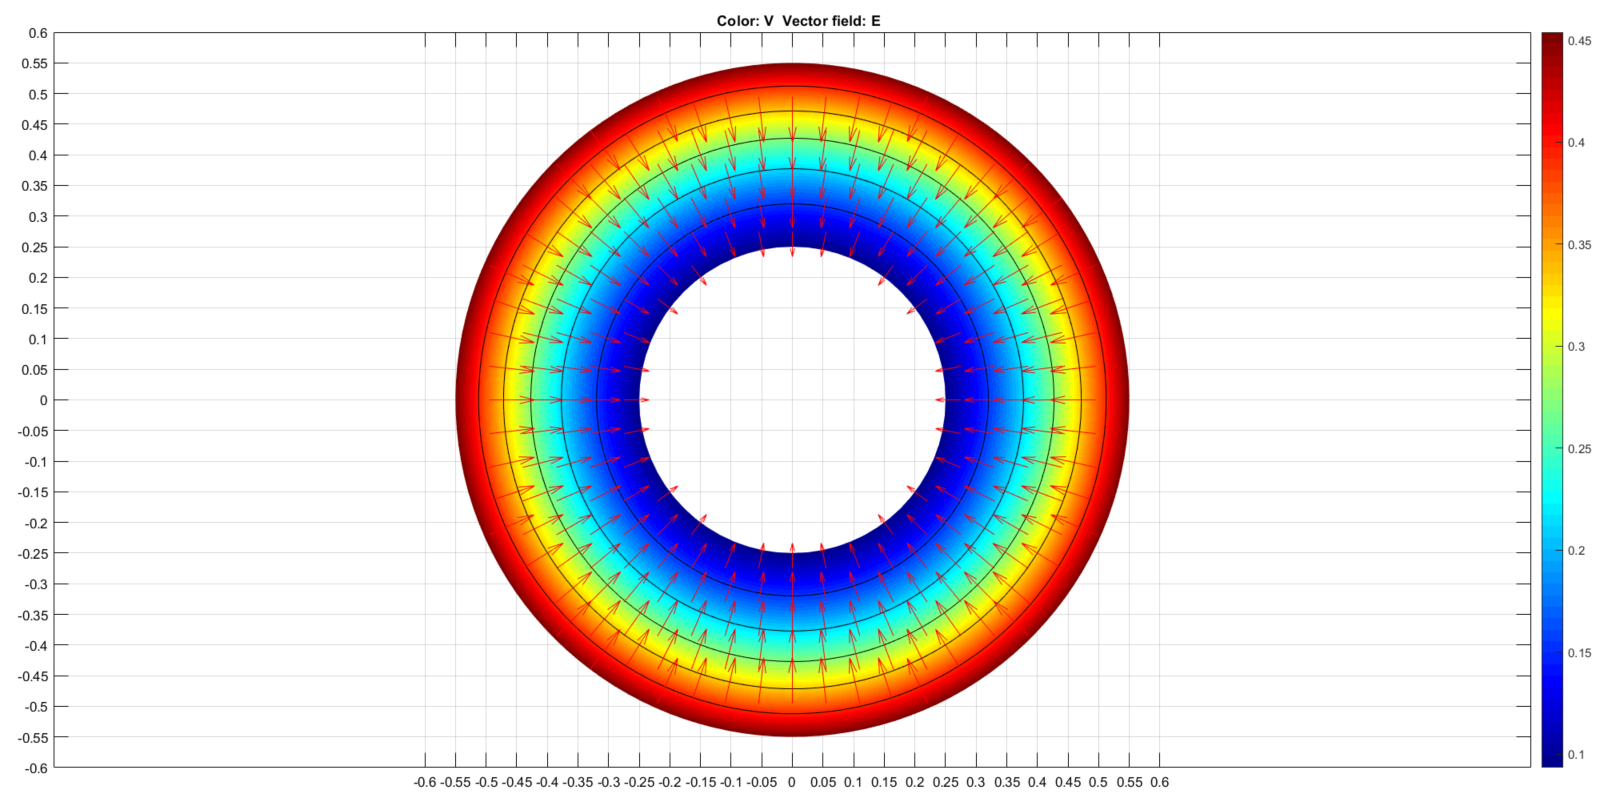

b) El error máximo de la aproximación, desde el propio *pdetool*, podría obtenerse mediante un plot de `abs(u-3/2*(x.^2+y.^2))`, que arroja un valor de aproximadamente 3.5E-4.

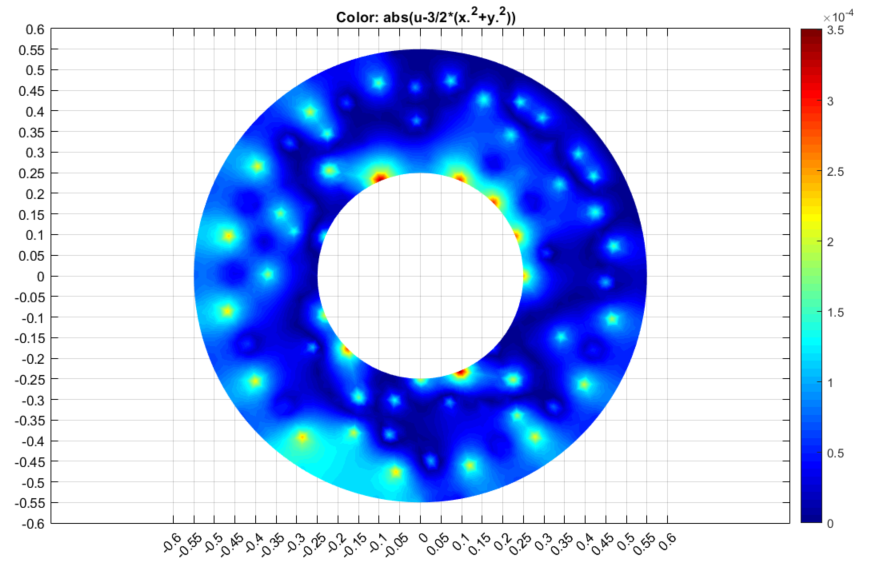

El error máximo en la aproximación del potencial es básicamente el apartado g) de la Práctica 8: el cálculo de la norma de una función en $L^{2}(\Omega)$, $\|v_{h}\|_{L^{2}(\Omega)}$ donde la función es la diferencia entre $u$ y $u_{h}$.

x=p(1,:)'; y=p(2,:)';
norm(u+3*(x.^2+y.^2)/2,Inf)

ans = 0.9076

c) Por otro lado, esto es exactamente el apartado h) de la Práctica 8: el cálculo del gradiente $\|\nabla v_{h}\|_{L^{2}(\Omega)}$ y cálculo del error de la aproximación.

[ux,uy]=pdegrad(p,t,u);
nel=size(t,2);
bar_e=[];
for k=1:nel
    bar_e=[bar_e, 1/3*[sum(p(1,t(1:3,k))), sum(p(2,t(1:3,k)))]'];
end
error2_grad_u=max(norm(ux+bar_e(1,:)/2,2), norm(uy+bar_e(2,:)/2,2))

error2_grad_u = 61.2348

Es interesante compararlo con el resultado que arroja el *pdetool*, que obtenemos haciendo *plot* de la función `sqrt((ux-3.*x).^2+(uy-3.*y).^2)`:

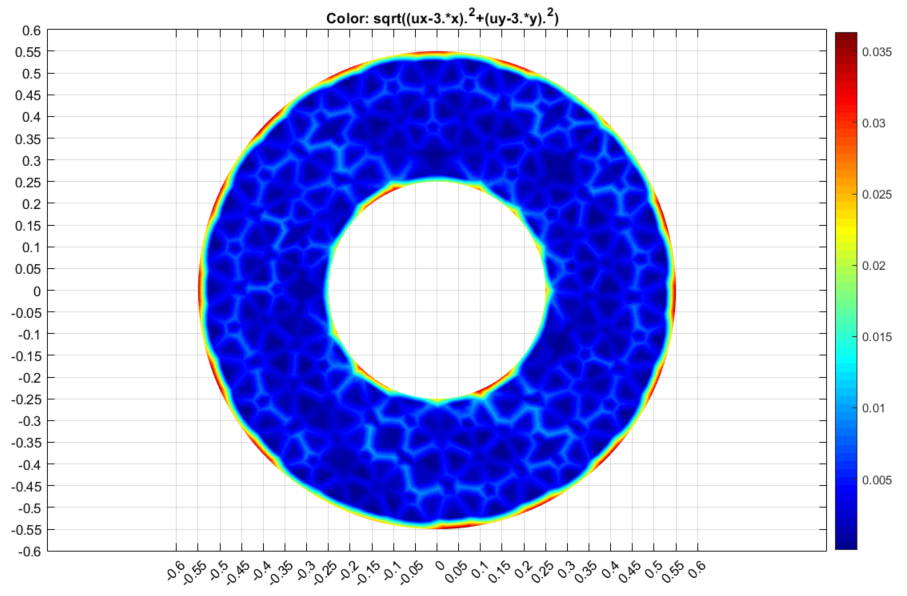

#### Ejercicio 2. Aplicación en transferencia de calor.

a) Se pide escribir el problema en coordenadar cilíndricas y utilizar la independencia respecto del ángulo. Para ello tomamos $\rho C_{p} \frac{\partial T}{\partial t}-\nabla \cdot(k \nabla T)=f$ y escribimos el gradiente en coordenadas cilíndricas: $\nabla T(t, r, \theta, z)=\frac{\partial T}{\partial r} \mathbf{e}_{r}+\frac{1}{r} \frac{\partial T}{\partial \theta} \mathbf{e}_{\theta}+\frac{\partial T}{\partial z} \mathbf{e}_{z}$. Sustituimos en la ecuación anterior para obtener $\rho C_{p} \frac{\partial T}{\partial t}-\nabla \cdot(k \frac{\partial T}{\partial r} \mathbf{e}_{r}+\frac{1}{r} \frac{\partial T}{\partial \theta} \mathbf{e}_{\theta}+\frac{\partial T}{\partial z} \mathbf{e}_{z})=f$; a su vez podemos escribir $\rho C_{p} \frac{\partial T}{\partial t}-\nabla \cdot(k \frac{\partial T}{\partial r} \mathbf{e}_{r}+k\frac{\partial T}{\partial z} \mathbf{e}_{z})=f$. Utilizamos la divergencia en cilíndricas ahora: $\rho C_{p} \frac{\partial T}{\partial t}-\left(\frac{1}{r} \frac{\partial}{\partial r}\left(r k\frac{\partial T}{\partial r}\right)+k\frac{\partial^{2}T}{\partial z^{2}}\right)=f$, que es efectivamente un problema bidimensional evolutivo.

b) Resolvemos el problema evolutivo asociado con los parámetros indicados en el enunciado: basta en abrir *pdetool* el archivo p9ej3.m:

pdetool;

c) Representar graficamente las isotermas y el flujo de calor sobre la sección vertical de $C$ correspondiente a $\theta$ = 0.

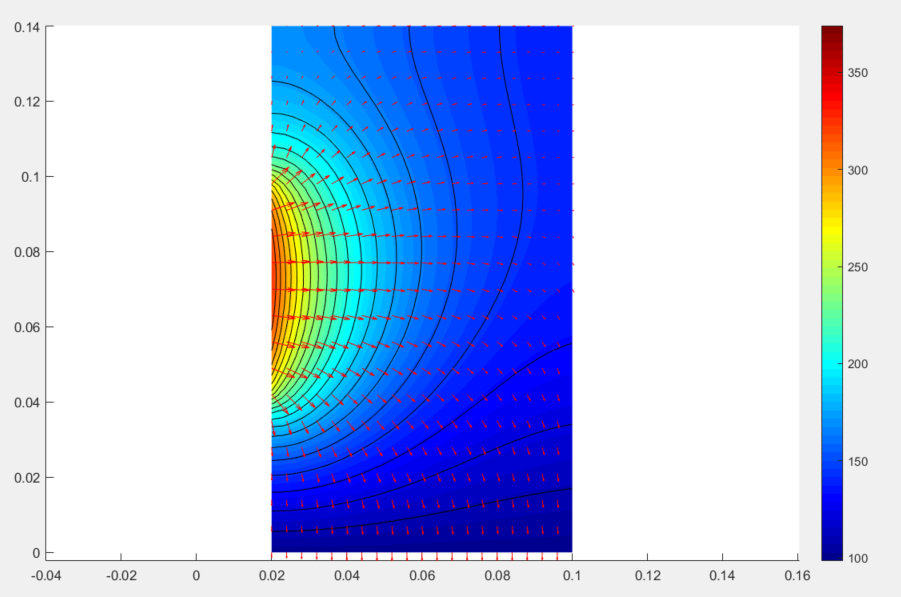

d) Exportar la solución calculada a la ventana de comandos. Calcular el flujo de calor sobre la superficie lateral exterior.

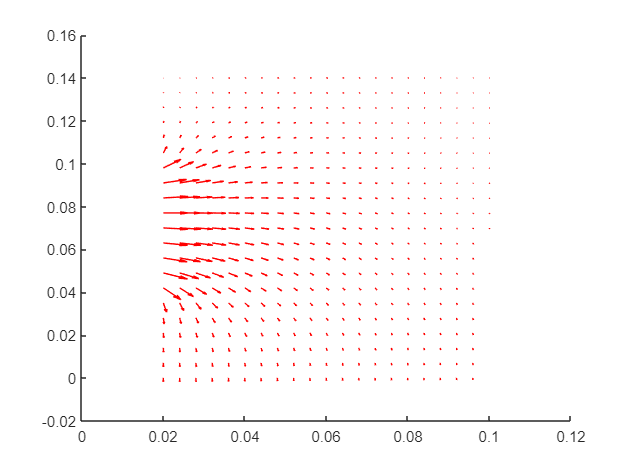

Tf=u(:,101); % flujo de calor en el instante t = 1000s
[Tx,Ty]=pdegrad(p,t,Tf);
pdeplot(p,e,t,'FlowData',-52*[Tx;Ty])

% Sobre la ventana del PDEtool se puede ver que las fronteras
% correspondientes a r=r_e son la 3, 4 y 5
% Extraemos primero qué aristas de la malla están es esas fronteras
aristas_r=[];
for ar=3:5
    aristas_r=[aristas_r, find((e(5,:)==ar))];
end
% Para hacer un test consideramos la frontera 7, para la cual es fácil
% calcular el flujo total
% Escribimos la interpolación del gradiente en los nodos de la malla
Txn=pdeprtni(p,t,Tx); % Valor de la componente x del gradiente en cada nodo.
Tyn=pdeprtni(p,t,Tx); % Valor de la componente y del gradiente en cada nodo.
% Encontrar a qué elemento pertenecen los elementos de r=r_e
flujo_r=0;
% %Normal en r=r_e
nx=1;ny=0;
%Normal en r=r_i
% nx=-1;ny=0;
for i=1:length(aristas_r)
    v1=e(1,aristas_r(i));v2=e(2,aristas_r(i)); % vértices en la arista i
    longi=norm(p(:,v2)-p(:,v1),2);% longitud arista i
    flujo_r=flujo_r-longi*52*((Txn(v1)+Txn(v2))*nx+(Tyn(v1)+Tyn(v2))*ny)/2;
end
disp(['El flujo a través de la frontera dada es ', num2str(flujo_r)])

El flujo a través de la frontera dada es 1144.6912
